Validate your Jacobian implementation by invoking the ‘get_jacobian(q)’ method. Pass it a 1x4 vector of joint variables that would take the manipulator to an overhead configuration i.e. the arm fully extended along the z0 axis. 

Calculate the determinant of the first three columns of the upper half of J (3x3 submatrix of J) and display it on screen (i.e., find Jp and only consider the first three joints). If your Jacobian calculation is correct, the first column of the Jacobian should contain all 0 (or very small numbers, close to 0) and its determinant should be 0 (or a very small number close to 0) at this configuration

calc=Lab2Step2();
m=Model(false);

Jac=calc.calculateJac([0,-10.51,-79.38,0])

Jac =          0    6.7654    4.4925    2.3283
    0.0130         0         0         0
         0   -0.0130   -0.0086   -0.0045
         0         0         0         0
         0    1.0000    1.0000    1.0000
    1.0000         0         0         0


out=det(Jac(1:3,1:3))

out = 7.9713e-07

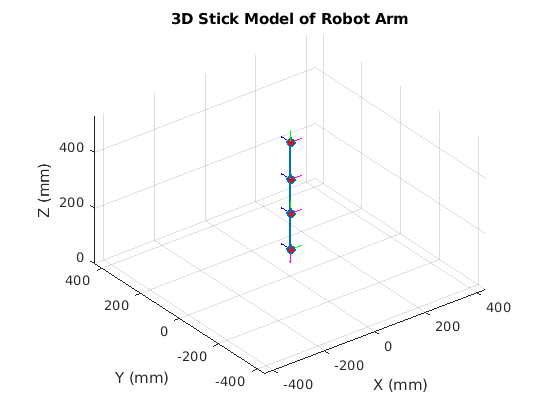

m.plot_arm([0,-10.51,-79.38,0]);